# **Uninfected**

## **GLOBULOS BLANCOS**

### **a) Anotaciones**

close all; clc; clearvars;
% Cargar carpeta del 1º paciente
imageFolder='C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\Uninfected\NIH-NLM-ThickBloodSmearsU\Uninfected Patients\TF201_HT6\tiled'; 

% Cargar imagenes del 1º paciente
imageFiles=dir(fullfile(imageFolder, '*.tiff'));

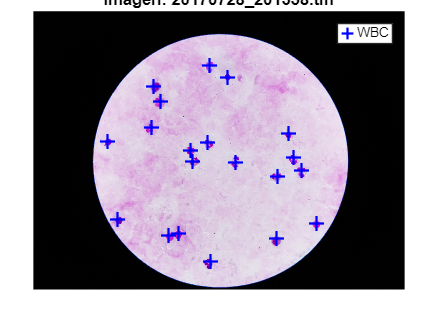

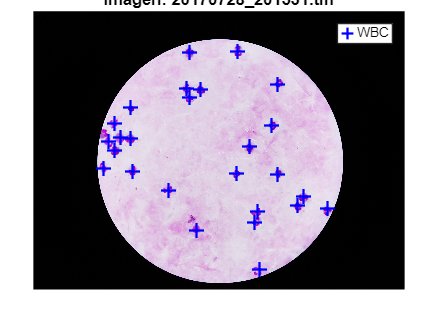

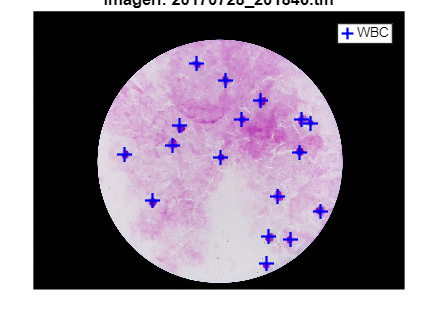

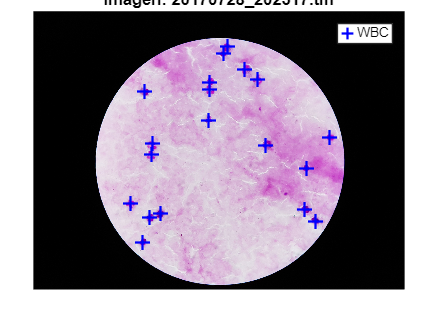

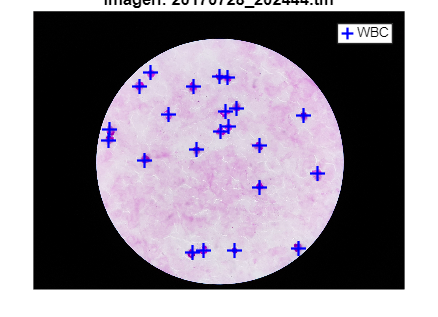

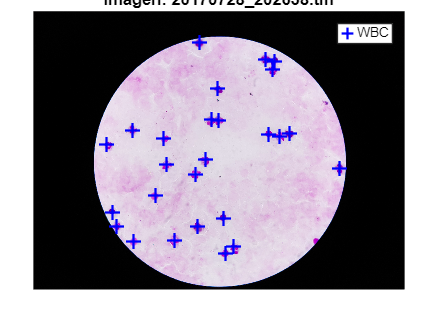

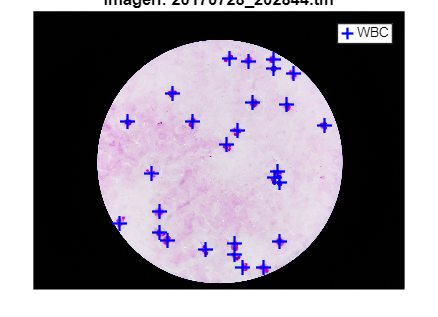

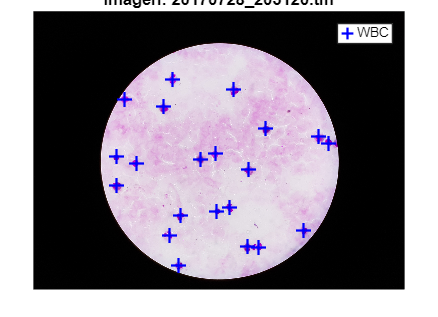

for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    figure;
    imshow(I); hold on;

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\Uninfected\NIH-NLM-ThickBloodSmearsU\Annotations\TF201_HT6\results\2546', [imageFiles(i).name(1:end-5), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== GLÓBULOS BLANCOS =====
    solo_WBC = datos(strcmp(datos.Var2, 'White_Blood_Cell'), :);
    x_wbc = solo_WBC.Var6;
    y_wbc = solo_WBC.Var7;
    plot(x_wbc, y_wbc, 'b+', 'MarkerSize', 10, 'LineWidth', 1.5);  % cruces azules

    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    legend('WBC');
    hold off;
end

## **PARÁSITOS**

**No debería de haber**

### c) 2º Modelo Otsu

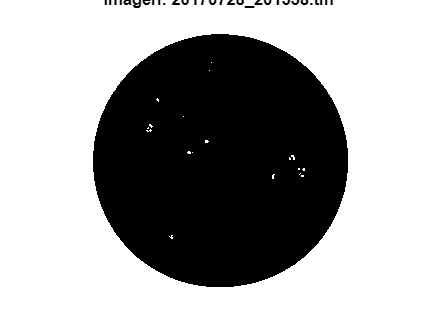

ruido = 50

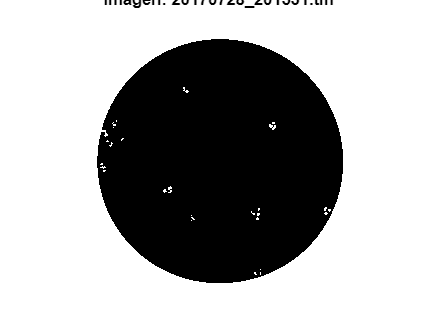

ruido = 56

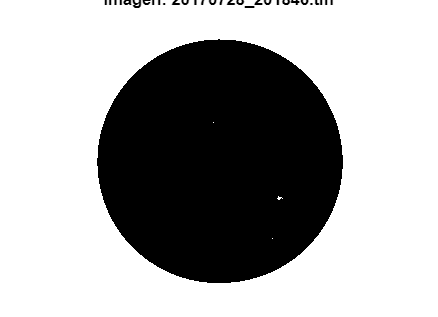

ruido = 18

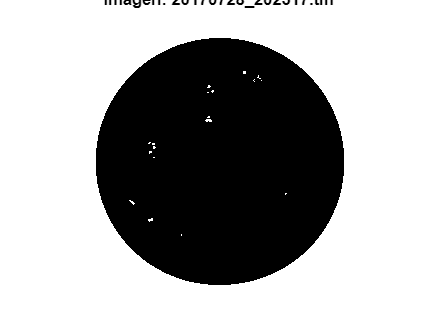

ruido = 40

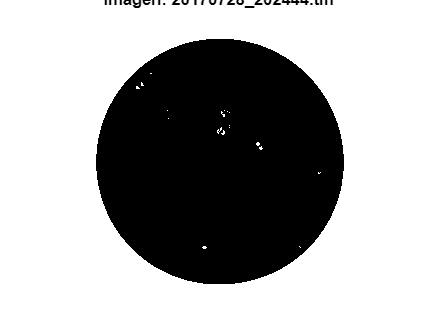

ruido = 46

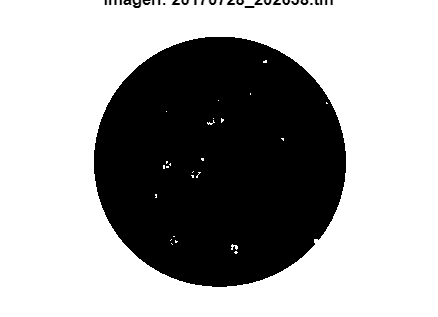

ruido = 48

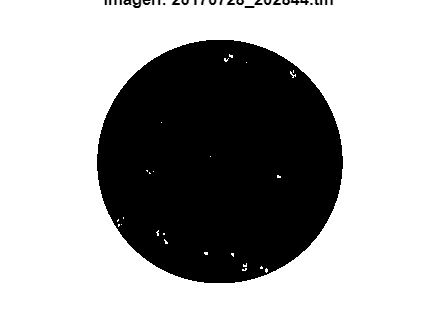

ruido = 43

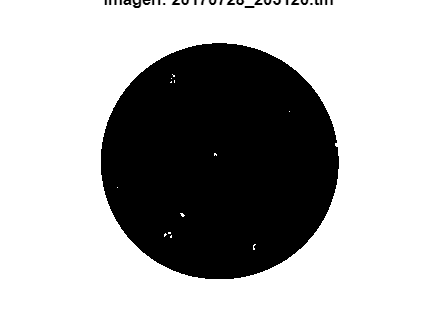

ruido = 27

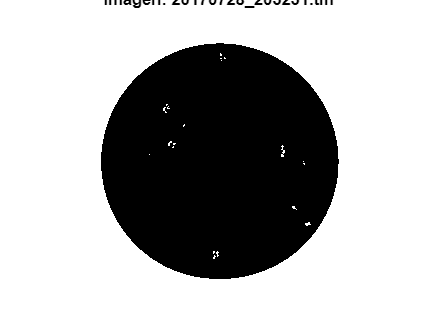

ruido = 42

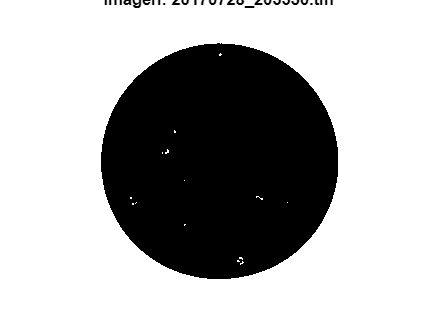

ruido = 38

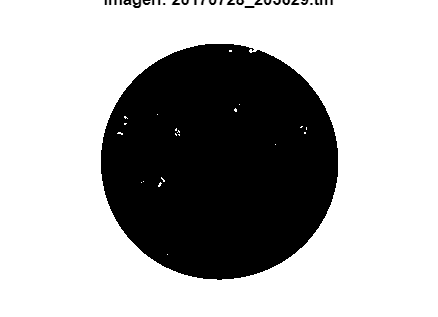

ruido = 49

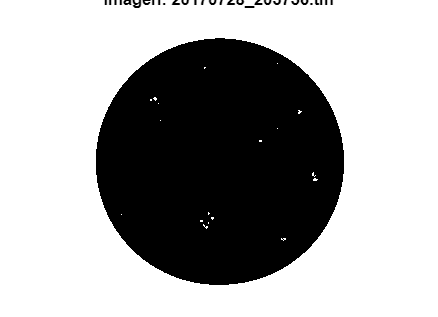

ruido = 26

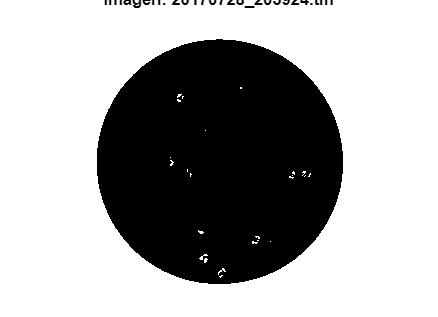

ruido = 53

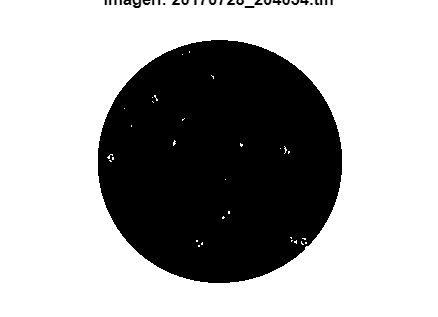

ruido = 73

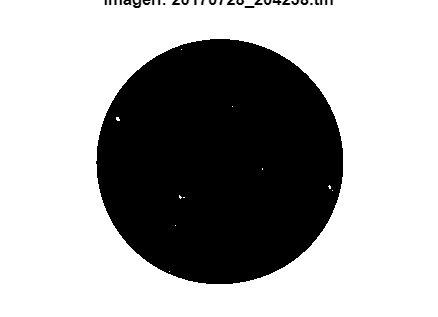

ruido = 15

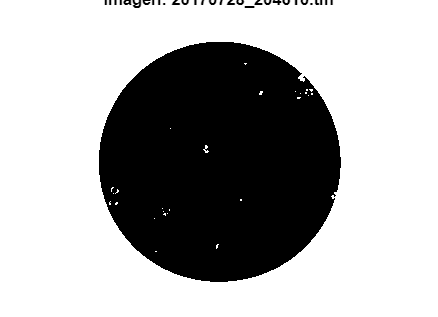

ruido = 48

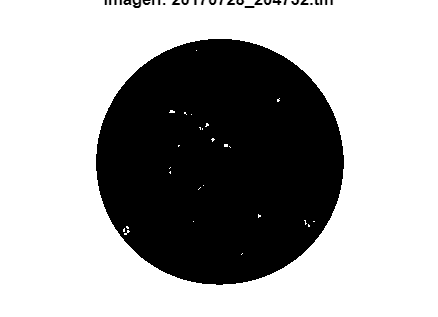

ruido = 61

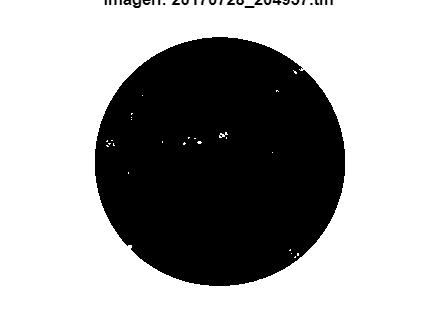

ruido = 62

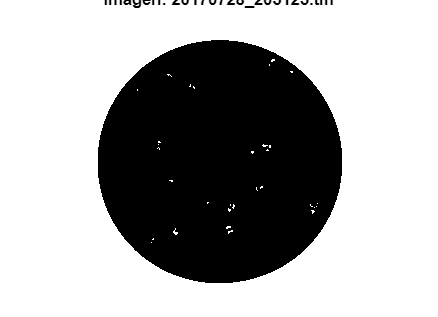

ruido = 64

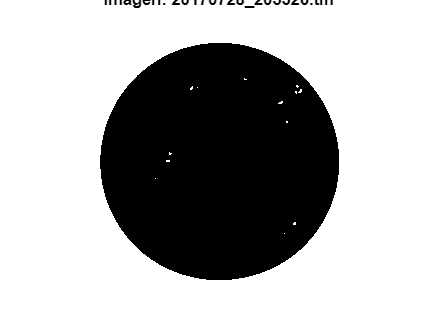

ruido = 57

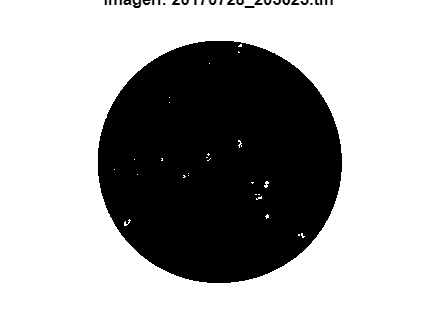

ruido = 51

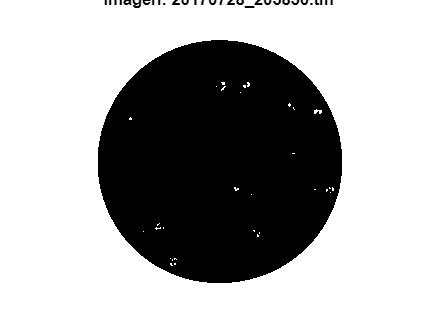

ruido = 62

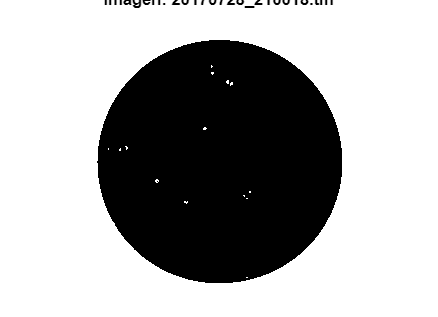

ruido = 28

total_ruido=0;
cantidad_imagenes_ruido=0;
for i = 1:length(imageFiles)
    % Fitxategiaren izen osoa
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    
    % Binario y escala de grises
    I_gray=im2double(rgb2gray(I));

    %====SEGMENTACIÓN===
    
    % 1. Filtro
    I_sinruido=medfilt2(I_gray, [3 3]);

    % 2. Umbral
    threshold = graythresh(I_sinruido)*0.95;

    % 3. Binarizar
    M1 = imbinarize(I_sinruido, threshold);

    % 4. Tener el negativo
    negativo= imcomplement(M1);

    % 5. Rellenar agujeros
    M2 = imfill(M1, 'holes');

    % 6. Separar WBCs
    WBC_mask_ruido = M2 & ~M1;

    % 7. Eliminar pequeños ruidos
    WBC_mask = bwareaopen(WBC_mask_ruido, 1500);

    % 8. Parasitos que se detecta cuando no debería de haber
    parasitos= negativo-WBC_mask;

    % Visualiza la máscara final
    figure;
    imshow(parasitos);
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    
    % Mirar las propiedades de los pixeles
    n=8; % neighbourhood

    % Contar puntos detectados
    CC = bwconncomp(parasitos,n);
    properties = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC,properties);
    ruido=size(caracteristicas,1)
    total_ruido=total_ruido+ruido;
    if ruido>=1
        cantidad_imagenes_ruido=cantidad_imagenes_ruido+1;
    end
end

total_ruido

total_ruido = 1057

cantidad_imagenes=length(imageFiles)

cantidad_imagenes = 23

media=total_ruido/cantidad_imagenes

media = 45.9565